# Angles

Calculate:

- The angle between two lines

- The intersection between two lines

## Select points

At least 4

cd ~/Documents/Polimi/IACV/
I = imread('images/checkerboard.png');

figure(1), imshow(I.*255); hold on;
[x, y] = getpts();

Create the lines connecting the pairs of points

a = [x(1); y(1); 1];
b = [x(2); y(2); 1];
c = [x(3); y(3); 1];
d = [x(4); y(4); 1];

lab = cross(a, b);
lcd = cross(c, d);

### Draw

x_coord = linspace(0, 500);
y1 = -lab(1)/lab(2) * x_coord - lab(3)/lab(2);
y2 = -lcd(1)/lcd(2) * x_coord - lcd(3)/lcd(2);
plot(x_coord, y1);
plot(x_coord, y2);

## Angle between lines

#### Using cartesian coordinates

% directions
l1 = lab(1:2);
l2 = lcd(1:2);
cos_theta1 = l1'*l2 / (norm(l1) * norm(l2));
theta1 = acos(cos_theta1) / pi * 180    % to degrees

theta1 = 45.7441

#### Using the absolute conic

C = [1 0 0; 
    0 1 0; 
    0 0 0];

cos_theta2 = lab' * C * lcd / sqrt((lab' * C * lab) * (lcd' * C * lcd));
theta2 = acos(cos_theta2) / pi * 180    % to degrees

theta2 = 45.7441

## Intersection

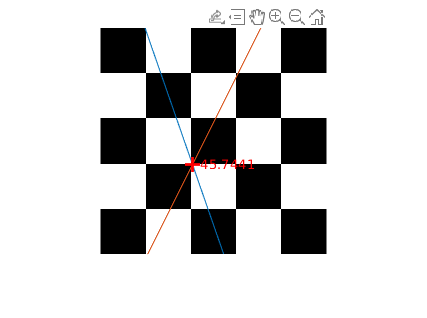

p = cross(lab, lcd);
p_x = p(1)/p(3);
p_y = p(2)/p(3);

plot(p_x, p_y, 'r+', MarkerSize=10, LineWidth=2);
text(p_x, p_y, "  " + theta1, 'Color', 'r');
hold off;